# Week 4 Lecture 2: Iterative Methods

## Rahman notes:

### Matrix iteration

Suppose we have the matrix equation $Ax = b$ where we can write $A = I-M$.  As we showed in the theory lecture, we can write a recurrence relation for the solution: $x_{n+1} = Mx_n + b$.  Further assume that this recurrence relation converges -- we can test for convergence by verifying the maximal eigenvalue is within unity in absolute value.  Then as $n \rightarrow \infty$, $x_n \rightarrow x$.  Lets see how this works in an example

n = 10;
A = eye(n) - 0.3*(rand(n) - 0.5);
M = eye(n) - A;
b = rand(n,1);
x = zeros(n,1);
format long

abs(max(eig(M)))

ans =    0.251533817252817


x = M*x + b

x =    0.487430654415445
   0.229468774748017
   0.085552232409057
   0.067383313608907
   0.888390934804578
   0.233167685669660
   0.861595759984367
   0.711735093007919
   0.872812993042854
   0.938002006919630


A*x-b

ans =   -0.002013723515043
  -0.204231959610134
  -0.097669424307830
  -0.292096388632028
  -0.360539653571561
  -0.190488525393780
   0.285871138270069
  -0.055089186065404
   0.215178563475392
   0.123845466747567


x = M*x + b

x =    0.489444377930489
   0.433700734358151
   0.183221656716887
   0.359479702240935
   1.248930588376139
   0.423656211063440
   0.575724621714299
   0.766824279073323
   0.657634429567462
   0.814156540172064


A*x-b

ans =   -0.027574491869534
   0.067591200268138
   0.105110877427748
   0.017340473449140
  -0.017182385126301
  -0.029134162894812
  -0.017787868719848
   0.083936818813111
  -0.108294323384642
   0.010806500955320


x = M*x + b

x =    0.517018869800023
   0.366109534090013
   0.078110779289139
   0.342139228791795
   1.266112973502441
   0.452790373958251
   0.593512490434147
   0.682887460260212
   0.765928752952103
   0.803350039216744


A*x-b

ans =   -0.026867157384740
  -0.020015075165060
  -0.007077147177931
  -0.002006947174130
  -0.017846949363620
  -0.001290835826448
   0.015012384213033
  -0.010311517868461
   0.019805534192268
  -0.021021919428328


x = M*x + b

x =    0.543886027184763
   0.386124609255072
   0.085187926467070
   0.344146175965925
   1.283959922866061
   0.454081209784699
   0.578500106221113
   0.693198978128673
   0.746123218759835
   0.824371958645072


A*x-b

ans =    0.000111849097241
   0.004306336620153
  -0.001750638049745
  -0.001153113554941
  -0.001610072073490
  -0.000279500073629
  -0.000729688189010
  -0.000559779556463
  -0.003062751790395
  -0.003216361521424


x = M*x + b

x =    0.543774178087522
   0.381818272634920
   0.086938564516816
   0.345299289520866
   1.285569994939551
   0.454360709858328
   0.579229794410124
   0.693758757685137
   0.749185970550230
   0.827588320166496


A*x-b

ans =    0.000049178133960
  -0.000843524864389
  -0.000106260438275
  -0.000147115087455
  -0.000360368566520
  -0.001116186131124
   0.000786166570861
  -0.000090676173330
   0.000011081844002
   0.000157410289766


### Jacobi Method

A "good" algorithm should be robust and fast.  Jacobi's algorithm is based around the additive decomposition of a matrix:  $A = L + D + U$.  As we showed in the theory lecture, this gives us the recurrence relation: $x_{n+1} = -D^{-1}(L+U)x_n + D^{-1}b$.  Lets see how this works through the following example.

A = diag([1, 2, 3, 4, 5]) + 0.1*randn(5);
L = tril(A,-1);
U = triu(A,+1);
D = diag(A);
b = ones(5,1);
x = zeros(5,1);

M = -(L+U)./D;
c = b./D;

x = M*x + c

x =    1.139856239273652
   0.542060186305467
   0.330036940404643
   0.243960470956883
   0.196893120280227


A*x - b

ans =    0.000502520298528
  -0.083186330059487
   0.105619136741367
  -0.056152268382438
   0.224389775459463



x = M*x + c

x =    1.139283438376013
   0.587152183875581
   0.295178723666342
   0.257659404796760
   0.152712317231034


A*x - b

ans =    0.002609159600117
  -0.007633496590633
   0.009150487681143
   0.003979121124793
  -0.001174056145986



x = M*x + c

x =    1.136309371526559
   0.591289998459662
   0.292158724708848
   0.256688656533161
   0.152943480809001


A*x - b

ans = 	1.0e+-3 *

  -0.370562651017203
   0.290319360532587
  -0.154453710561664
  -0.442263769792617
  -0.483042075131168



x = M*x + c

x =    1.136731759676363
   0.591132627893004
   0.292209700138916
   0.256796551410727
   0.153038588470400


A*x - b

ans = 	1.0e+-4 *

  -0.093381289966166
  -0.365445271449660
   0.205790660408045
   0.095442320962036
   0.801540259121047



x = M*x + c

x =    1.136742403800963
   0.591152437226196
   0.292202908286923
   0.256794222995370
   0.153022806694135


A*x - b

ans = 	1.0e+-5 *

   0.159887524309177
  -0.088597476799457
   0.411634658714633
   0.128483866279616
   0.291061977319984


Notice that I used elementwise division with a column vector containing the diagonal elements of the diagonal matrix.  This is because, as I showed before, the inverse of the diagonal matrix is just the reciprocal of the diagonal entries, which is precisely what the elementwise division with the column vector gives us.  I encourage you to write it out with pen and paper to convince yourselves that this is true.  This elementwise division is much faster than what is done in the Older Notes towards the bottom of this document.

### Gauss-Seidel Algorithm

Similarly for Gauss Seidel we have the recurrence relation: $x_{n+1} = -(L+D)^{-1}Ux_n + (L+D)^{-1}b$.  

A = diag([1, 2, 3, 4, 5]) + 0.1*randn(5);
LpD = tril(A);
U = triu(A,+1);
b = ones(5,1);
x = zeros(5,1);
M = -LpD\U;
c = LpD\b;

x = M*x + c

x =    1.070008787529781
   0.423495099866080
   0.371500756261595
   0.249102375083878
   0.222293259208023


A*x - b

ans =    0.089997828538895
   0.046936985291919
   0.028022279202131
   0.010809733591860
  -0.000000000000000



x = M*x + c

x =    0.973710320134565
   0.406419965752017
   0.358306298512243
   0.245328011905763
   0.221859365901821


A*x - b

ans =   -0.002260743473164
   0.000598568539725
  -0.000487566628370
  -0.000021099474919
  -0.000000000000000



x = M*x + c

x =    0.976129335517202
   0.405980387597088
   0.358572090908906
   0.245359466817209
   0.221855487253293


A*x - b

ans = 	1.0e+-4 *

  -0.057700159953322
  -0.136142982167797
   0.042241537960841
  -0.001886119148642
  -0.000000000001110



x = M*x + c

x =    0.976135509485021
   0.405986663700571
   0.358570925134427
   0.245359668720687
   0.221855483624712


A*x - b

ans = 	1.0e+-6 *

   0.325132819112284
   0.031076682782682
   0.026657628104942
  -0.000176451409040
  -0.000000000111022



x = M*x + c

x =    0.976135161590048
   0.405986669677260
   0.358570901556032
   0.245359664269696
   0.221855484180486


A*x - b

ans = 	1.0e+-8 *

  -0.159790747300548
   0.138606459643142
  -0.059788263229166
   0.002702638113306
  -0.000000022204460


### Comparing Jacobi and Gauss-Seidel

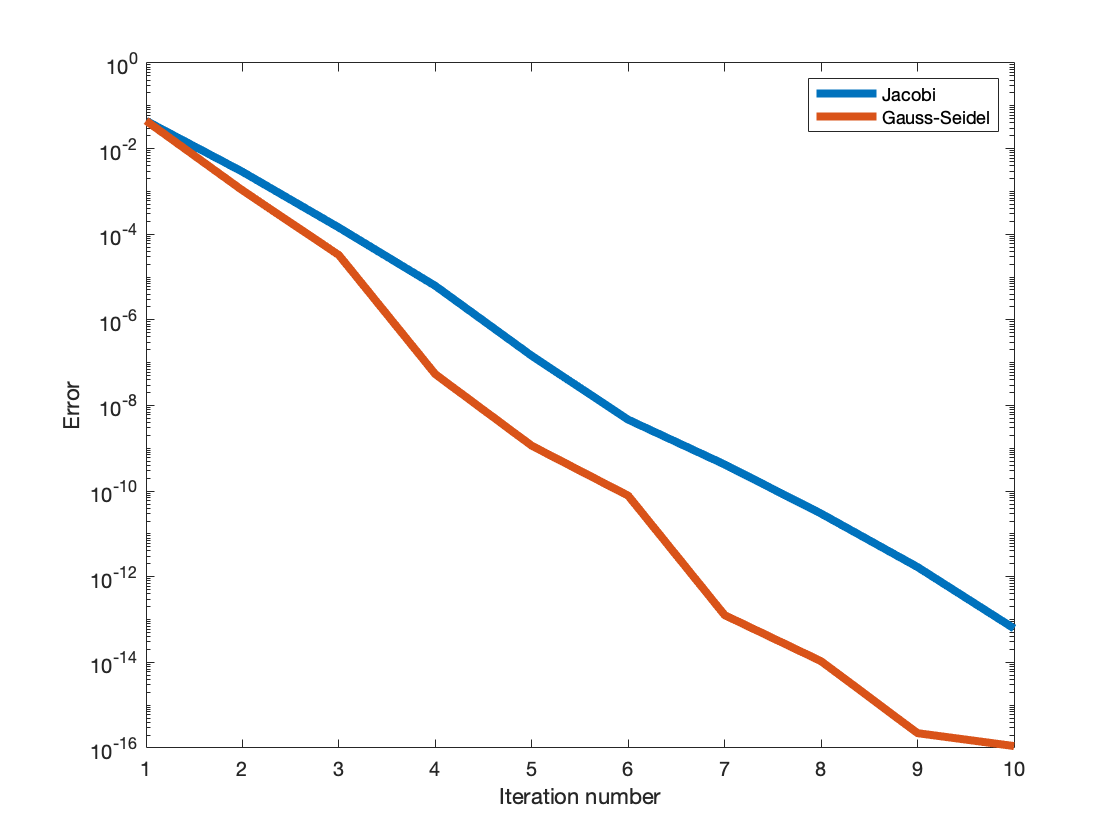

A = diag([1, 2, 3, 4, 5]) + 0.1*randn(5);
L = tril(A,-1);
LpD = tril(A);
U = triu(A,+1);
D = diag(A);
b = ones(5,1);
M_j = -(L+U)./D;
c_j = b./D;
M_gs = -LpD\U;
c_gs = LpD\b;

x_j = zeros(5,1);
x_gs = zeros(5,1);

TrueSol = A\b;

T = 10;
err_gs = zeros(1,T);
err_j = zeros(1,T);

for i = 1:T
    x_j = M_j*x_j + c_j;
    x_gs = M_gs*x_gs + c_gs;
    err_j(i) = max(abs(x_j - TrueSol));
    err_gs(i) = max(abs(x_gs - TrueSol));
end
semilogy([1:T], err_j, [1:T], err_gs, 'Linewidth', 4)
legend('Jacobi', 'Gauss-Seidel')
xlabel('Iteration number')
ylabel('Error')

Notice that we used the function "semilogy", which gives us a log scale on the vertical axis (the ordinate).  If we had used the usual plot function it would have looked like utter ....  Compare:

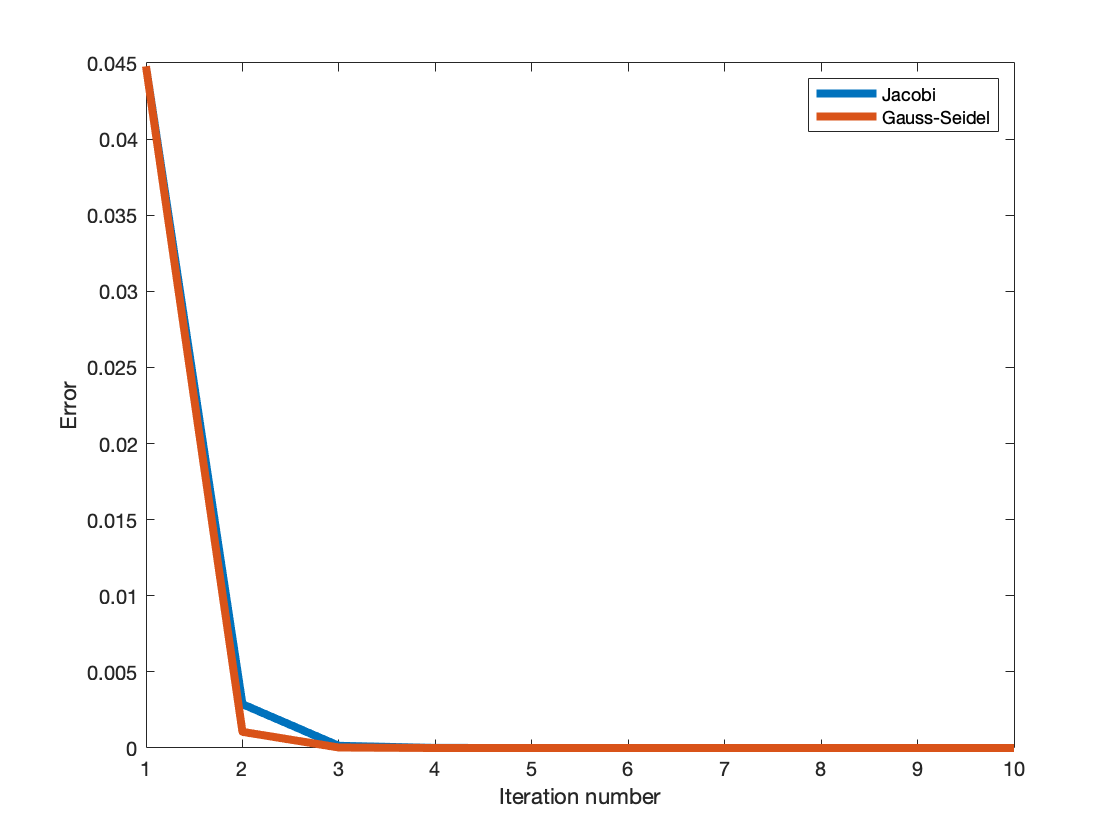

plot([1:T], err_j, [1:T], err_gs, 'Linewidth', 4)
legend('Jacobi', 'Gauss-Seidel')
xlabel('Iteration number')
ylabel('Error')

## Older notes:

### Jacobi method

One of the easiest types of systems to solve is a diagonal system.  That is, if $P$ is a matrix with zeros everywhere except the main diagonal, then it is very fast to solve $P\mathbf{x} = \mathbf{c}$.  (You wrote your own diagonal system solver in the last activity, but the backslash command will be fast enough for our purposes.)  It is easy to check that we can solve such a system in $\mathcal{O}(N)$ steps, since finding each variable only involves a single division step.  It would therefore be convenient to choose a diagonal matrix for $P$ in our splitting method.  If we choose $P$ as the diagonal matrix with the same diagonal entries as $A$, then our method is called the *Jacobi method*.  That is, we should choose 

$P = \left(\begin{array}{c} 6 & 0 & 0 \\ 0 & 8 & 0 \\ 0 & 0 & 9 \end{array}\right)$ and $T = \left(\begin{array}{c} 0 & 1 & 1 \\ 1 & 0 & 2 \\ 2 & 3 & 0 \end{array}\right)$.  

(Remember, we have to choose $T = A - P$ to satisfy the requirement for a matrix splitting method.)  We could type these matrices out in MATLAB, but there is a convenient function in MATLAB called `diag` that will make this easier.  The `diag` command has two basic uses.  If you use a matrix as input, then `diag` returns a vector containing the main diagonal entries of $A$.  If you use a vector as input, then `diag` returns a diagonal matrix with the same non-zero entries as the given vector.  This means that we can make the matrix $P$ with two calls to `diag`.  

P = diag(diag(A))

P =    1.126790208092984                   0                   0                   0                   0
                   0   2.253497468773507                   0                   0                   0
                   0                   0   2.980273621055439                   0                   0
                   0                   0                   0   4.084650066455870                   0
                   0                   0                   0                   0   4.896645838730008


T = A - P

T =                    0  -0.005840338194651  -0.130750261602475   0.089595406000116  -0.116110152841623
   0.109051420554461                   0   0.079414271542165  -0.181348642042825  -0.039753570256193
  -0.094645061033580   0.043864543776020                   0   0.156668345394797   0.025429431104049
  -0.043849914361070   0.043751771799850   0.064915281625448                   0   0.120778943607426
   0.034322067226553  -0.083767599518706  -0.083147427215967   0.011015483625554                   0


We can check that our method will converge by finding the magnitude of all the eigenvalues of $M = -P^{-1}T$.  

M = -P\T;
e = abs(eig(M))

e =    0.047158817013610
   0.047158817013610
   0.047135187619854
   0.008270156616781
   0.026012708582710


max(e)

ans =    0.047158817013610


Since the largest eigenvalue (and therefore all of the eigenvalues) is smaller than 1, the Jacobi method will converge for this problem.  

To begin a matrix splitting method, we need to make some initial guess for our solution.  We already showed that the choice of guess does not affect the convergence of our method, so it does not particularly matter what we choose here.  It is common to choose a random vector in situations like this, but we will choose a vector of all ones for no particular reason.  

x0 = ones(3, 1);

We can now use the equation 


$$\mathbf{x}_k = P^{-1}\left(-T\mathbf{x}_{k-1} + \mathbf{b}\right)$$


to implement our algorithm.  Remember, you should use the backslash command in place of matrix inverses in MATLAB, so we could find the next guess using 

x1 = P\(-T*x0 + b)

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Related documentation

This is closer to the true solution than before, so it seems like we are on the right track.   We can continue this process with 

x2 = P\(-T*x1 + b)
x3 = P\(-T*x2 + b)
x4 = P\(-T*x3 + b)

These first few guesses do seem to confirm that we are converging to the correct solution, but it should also be clear that we don't want to continue this process by hand.  Since we are repeating almost the same code over and over again, it is probably a good idea to use a loop.  Since we don't know how many steps we need, this is actually a good place for a while loop, but we will start with a for loop because they tend to be easier to understand.  

#### Jacobi method (version 1)

As a (very rough) first pass, we can try the following: 

A = [6 1 1; 1 8 2; 2 3 9];
b = [10; -8; -8];
P = diag(diag(A));
T = A - P;

x0 = ones(3, 1);
for k = 1:100
    x1 = P\(-T*x0 + b);
end

This doesn't really do what we want, since it just calculates the first guess over and over again.  We need to somehow keep track of our guesses as we go.  

#### Jacobi method (version 2)

There are several ways to do this, but we will try storing all of our guesses in a big matrix.  (We actually only ever need the last two guesses, but it might be convenient to have a record of all our guesses for analysis.)  In particular, we will make a matrix `X` where every column is supposed to represent one of our guesses.  Since our loop needs access to the initial guess, we will need to put this initial guess into our matrix as well.  

Remember that we always want to initialize our matrices by creating an "empty" matrix of the right size before we start our loop.  However, we don't know how many guesses we will actually need, so we don't know how big to make our matrix.  There is not really an ideal way around this problem, but we will start by making space for 101 columns, because our loop repeats 100 times (plus one column for the initial guess): 

A = [6 1 1; 1 8 2; 2 3 9];
b = [10; -8; -8];
P = diag(diag(A));
T = A - P;

x0 = ones(3, 1);
X = zeros(3, 101);
X(:, 1) = x0;

Notice that the numbers here don't seem to match: The guess `x0` is going into column 1.  This is a common stumbling block in numerical programming, which you have probably already encountered in the homework.  In math it makes perfect sense to start a variable (like $k$) at 0 or to increment it by some value other than 1.  (For instance, we might want to keep track of time in units of 0.01 seconds.)  However, MATLAB always counts columns and rows with whole numbers and always starts counting at 1.  Therefore, we need to think of our initial guess as $\mathbf{x}_0$ but we have to store it in `X(:, 1)`.  The next guess will be $\mathbf{x}_1$, but we will store it in `X(:, 2)` and then the next guess will be $\mathbf{x}_2$ and we will store it in `X(:, 3)`, etc.  It is important to remember this and mentally translate between the two (or better yet, write yourself explanatory comments), because MATLAB doesn't know the difference.  

We are now in a position to fix our loop.  At every step, we want to update the next guess using our last guess.  Turning this into code, we have 

for k = 1:100
    X(:, k+1) = P\(-T*X(:, k) + b);
end

If you look at the matrix `X`, you should see that the columns are now filled with our guesses (and the first five columns match our old answers).  You should also notice that our method converged successfully, since the last column is the true solution to $A\mathbf{x} = \mathbf{b}$.  In fact, our method seemed to converge in much fewer than 100 steps, since the last twenty or so columns are all exactly the same.  

#### Jacobi method (version 3)

The reason our method kept running after finding the correct answer is because we didn't include our stopping criterion.  Remember, we decided to stop if the difference between our last two guesses was smaller than some predefined tolerance.  We can fix our code by adding an `if` `break` combination, just like in the bisection method. 

A = [6 1 1; 1 8 2; 2 3 9];
b = [10; -8; -8];
P = diag(diag(A));
T = A - P;
tolerance = 1e-8;

x0 = ones(3, 1);
X = zeros(3, 101);
X(:, 1) = x0;

for k = 1:100
    X(:, k+1) = P\(-T*X(:, k) + b);
    if max(abs(X(:, k+1) - X(:, k))) < tolerance
        break
    end
end

This appears to have worked.  It converged to within about 8 decimal places of the correct answer after only 25 guesses (including the initial guess).  The rest of the matrix `X` is all zeros, because our loop stopped before filling in those columns.  We can chop off these extra zeros with the code 

X = X(:, 1:(k+1))

X =     1.0000    1.3333    2.1366    1.9221    2.0301    1.9868    2.0055    1.9976    2.0010    1.9996    2.0002    1.9999    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000   -1.3750   -0.8056   -1.0854   -0.9665   -1.0152   -0.9939   -1.0027   -0.9989   -1.0005   -0.9998   -1.0001   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
    1.0000   -1.4444   -0.7269   -1.0952   -0.9542   -1.0179   -0.9920   -1.0033   -0.9986   -1.0006   -0.9997   -1.0001   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000


This is essentially a working version of the Jacobi method, but there is one more issue to watch out for.  It is entirely possible to come up with problems that take many more steps to converge.  However, our code will only run for 101 guesses before stopping (because the for loop only runs for 100 steps).  If that is not enough guesses, then our code will produce the wrong answer.  You can always tell if this happened, because after running the script `k` would be 100.  

A simple fix is just to make our for loop run for more steps, but it is pretty inconvenient to have to run our code over and over again to find the right number of steps.  

#### Jacobi method (version 4)

A better solution is probably to use a while loop instead of a for loop.  This will avoid the issue of needing to guess a maximum number of steps, at the cost of complicating our code a little bit: 

A = [6 1 1; 1 8 2; 2 3 9];
b = [10; -8; -8];
P = diag(diag(A));
T = A - P;
tolerance = 1e-8;

x0 = ones(3, 1);
X = zeros(3, 101);
X(:, 1) = x0;
k = 1;

err = tolerance + 1;
while err >= tolerance
    X(:, k+1) = P\(-T*X(:, k) + b);
    err = max(abs(X(:, k+1) - X(:, k)));
    k = k + 1;
end
X = X(:, 1:k)

X =     1.0000    1.3333    2.1366    1.9221    2.0301    1.9868    2.0055    1.9976    2.0010    1.9996    2.0002    1.9999    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000   -1.3750   -0.8056   -1.0854   -0.9665   -1.0152   -0.9939   -1.0027   -0.9989   -1.0005   -0.9998   -1.0001   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
    1.0000   -1.4444   -0.7269   -1.0952   -0.9542   -1.0179   -0.9920   -1.0033   -0.9986   -1.0006   -0.9997   -1.0001   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000


There are a few important differences to notice here.  First, we have to keep track of `k` ourselves, which means we have to set a starting value and to increment it in the loop.  Second, the stopping condition is now at the top of the while loop, but it is backwards.  This is because the `if` `break` combo tests when to stop, but the `while` loop condition tests when to keep going.  We should keep guessing as long as our error is larger than the tolerance.  Third, we initialized the error to a strange value: `tolerance + 1`.  The reason for this is that the while loop needs to know the error in order to test its condition.  We don't actually have an error before we make our second guess, so we have to make up an error value that will ensure we continue.  Since `tolerance + 1` is greater than `tolerance`, we know that the while loop will execute at least one step.  

**Warning:** This code is substantially slower than the corresponding for loop version, because once k gets larger than 100 MATLAB will have to resize the matrix X at every step.  This resizing requires copying the matrix and is therefore quite slow.  This loss of speed is unavoidable if we want to store all of our guesses without first initializing a big enough array.  

The one thing you should always be wary of with `while` loops is the risk of infinite loops.  This is particularly important with matrix splitting methods, because we know that they might not converge even if the system $A\mathbf{x} = \mathbf{b}$ has a solution.  For example, if we made a mistake when entering $A$ and accidentally used this code: 

you would find that your code ran forever.  Even though the only difference between this and the previous version is that we swapped two entries of $A$.  (Actually, this particular example does eventually terminate, but it takes many thousands of steps and eventually gives an answer of `NaN`'s and `Inf`'s.)  

#### Jacobi method (version 5)

We know one way to fix this: We could first test the eigenvalues of $M$ to see if they are less than one.  

A = [6 1 1; 1 8 2; 2 3 9];
b = [10; -8; -8];
P = diag(diag(A));
T = A - P;
tolerance = 1e-8;

x0 = ones(3, 1);
X = zeros(3, 101);
X(:, 1) = x0;
k = 1;

err = tolerance + 1;

if max(abs(eig(-P\T))) < 1
    while err >= tolerance
        X(:, k+1) = P\(-T*X(:, k) + b);
        err = max(abs(X(:, k+1) - X(:, k)));
        k = k + 1;
    end
end
X = X(:, 1:k)

X =     1.0000    1.3333    2.1366    1.9221    2.0301    1.9868    2.0055    1.9976    2.0010    1.9996    2.0002    1.9999    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000   -1.3750   -0.8056   -1.0854   -0.9665   -1.0152   -0.9939   -1.0027   -0.9989   -1.0005   -0.9998   -1.0001   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
    1.0000   -1.4444   -0.7269   -1.0952   -0.9542   -1.0179   -0.9920   -1.0033   -0.9986   -1.0006   -0.9997   -1.0001   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000


#### Strict diagonal dominance

This last method is fairly tempting, but it raises an important question that we have so far avoided.  How long does it take to find the eigenvalues of a matrix?  The point is this: We want to solve $A\mathbf{x} = \mathbf{b}$ with a method that is faster than $\mathcal{O}(n^3)$.  We don't know exactly how many steps the Jacobi method will require, but each step only takes $\mathcal{O}(n)$ flops (well, technically it takes $\mathcal{O}(N^2)$ flops still, because multiplying $T\mathbf{x}_{k-1}$ is $\mathcal{O}(N^2)$, but the point still applies), so there is hope that it will ultimately be faster than Gaussian elimination.  However, if we have to start our method with a call to `eig` then we should worry that `eig` might take so long that we might as well just use Gaussian elimination in the first place.   

It turns out that our fears are well founded.  Most methods to find eigenvalues are iterative, so big-oh notation doesn't necessarily apply, but it is not uncommon for the `eig` command to take at least as long as Gaussian elimination.  This means that if we are forced to check the eigenvalues of $-P^{-1}T$ before we use a splitting method, we won't actually save any time over just using the backslash operator.  

Fortunately, there are some other properties of our system that can tell us about the convergence of matrix splitting methods.  The most important such property is called *strict diagonal dominance*.  We say that a matrix is strictly diagonally dominant if the absolute value of each diagonal entry is greater than the sum of the absolute values of the other entries in that row.  That is, $A$ is strictly diagonally dominant if 


$$|a_{ii}| > \sum_{j \neq i}|a_{ij}|,$$
 

for all $i \leq n$.  (The summation notation means to add up every entry in the row except $|a_{ii}|$.)  This property is much easier to check than the eigenvalues of a matrix.  We will make use of the following theorem without proving it: 

The Jacobi method for solving $A\mathbf{x} = \mathbf{b}$ will converge if $A$ is strictly diagonally dominant.  

There are a few things worth noting about this theorem.  First, this is a property of $A$, not of $M$.  You need to check if the original left hand side of your system is strictly diagonally dominant.  Second, this theorem says nothing about what happens when $A$ is not strictly diagonally dominant.  It is entirely possible to come up with such a system where the Jacobi method still converges.  If $A$ is not strictly diagonally dominant, then you still have to find the eigenvalues of $M$ to decide if the Jacobi method will converge.  Third, this theorem does not apply to all matrix splitting methods.  If you choose a different $P$ and $T$, there is no guarantee that the corresponding splitting method will converge.  

This also explains why our original example converged.  In the first row, we had $|6| >|1|+|1|$.  In the second row, we had $|8|>|1|+|2|$.  In the third row, we had $|9|>|2|+|3|$.  

### Gauss-Seidel method

Another type of system that is relatively easy to solve is a triangular system.  If we chose $P$ to be triangular, then we could solve systems of the form $P\mathbf{x} = \mathbf{c}$ in $\mathcal{O}(n^2)$ flops, which is still much faster than Gaussian elimination.  We could therefore choose $P$ to be a triangular portion of the matrix $A$.  In particular, if we choose $P$ to be the main diagonal of $A$ and all the entries below it, then $P$ will be lower triangular.  We call the matrix splitting method with this choice of $P$ the *Gauss-Seidel method*.  For example, in our example system we would choose 

$P = \left(\begin{array}{c} 6 & 0 & 0 \\ 1 & 8 & 0 \\ 2 & 3 & 9 \end{array}\right)$ and $T = \left(\begin{array}{c} 0 & 1 & 1 \\ 0 & 0 & 2 \\ 0 & 0 & 0 \end{array}\right)$.  

There is a useful command in Matlab for extracting the lower triangular portion of a matrix called `tril`.  We can make this splitting with the code 

A = [6 1 1; 1 8 2; 2 3 9];
P = tril(A)

P =      6     0     0
     1     8     0
     2     3     9


T = A - P

T =      0     1     1
     0     0     2
     0     0     0


Besides the different choices of $P$ and $T$, the Gauss-Seidel method works exactly the same as the Jacobi method.  

We can test that the Gauss-Seidel method will converge by checking the eigenvalues of $M = -P^{-1}T$.  

M = -P\T;
max(abs(eig(M)))

ans = 0.0962

Since all of the eigenvalues are less than 1, this method will converge.  

It turns out that the strict diagonal dominance test also works for the Gauss-Seidel method.  If $A$ (not $M$) is strictly diagonally dominant, then the Gauss-Seidel method will converge.  Again, this rule doesn't tell you what happens if $A$ is not strictly diagonally dominant.  It is entirely possible for one or both of the Jacobi and Gauss-Seidel methods to converge if $A$ is not strictly diagonally dominant.  

To code the Gauss-Seidel method, we could use version 4 of the code from above with our new $P$ and $T$: 

A = [6 1 1; 1 8 2; 2 3 9];
b = [10; -8; -8];
P = tril(A);
T = A - P;
tolerance = 1e-8;

x0 = ones(3, 1);
X = zeros(3, 101);
X(:, 1) = x0;

for k = 1:100
    X(:, k+1) = P\(-T*X(:, k) + b);
    if max(abs(X(:, k+1) - X(:, k))) < tolerance
        break
    end
end
X = X(:, 1:k+1)

X =     1.0000    1.3333    2.0216    2.0091    2.0010    2.0001    2.0000    2.0000    2.0000    2.0000    2.0000
    1.0000   -1.4167   -1.0745   -1.0061   -1.0001   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
    1.0000   -0.7130   -0.9800   -1.0000   -1.0002   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000


Notice that this method converged in fewer steps than the Jacobi method.  We already knew this would happen because the largest eigenvalue of $M$ for the Jacobi method was approximately $0.4236$, while the largest eigenvalue of $M$ for the Gauss-Seidel method was approximately $0.0962$.  The smaller the eigenvalue, the faster the splitting method, so we would expect Gauss-Seidel to converge faster for this problem.  This is actually fairly common.  As a rule of thumb, if both the Gauss-Seidel and the Jacobi method converge for a given problem, then Gauss-Seidel will typically be about twice as fast.  However, it is possible to find methods where one method converges and the other does not or where both converge but the Jacobi method is faster.  In general, if you want to find the fastest method there is no substitute for checking the maximum eigenvalue of $M$.  